# Import and Preprocess Data

## Import Data (2-5)

Use [`readtable`](matlab: doc readtable) to import `superConElements.csv` and `superConFeatures.csv.`

elements = readtable("superConElements.csv")

elements = 21263×88 table
    H    He    Li    Be    B    C    N    O    F    Ne    Na    Mg    Al    Si    P    S    Cl    Ar    K    Ca    Sc    Ti    V    Cr    Mn    Fe    Co    Ni     Cu     Zn    Ga    Ge    As    Se    Br    Kr    Rb     Sr     Y    Zr    Nb    Mo    Tc<

features = readtable("superConFeatures.csv", "VariableNamingRule", "preserve")

features = 15542×83 table
               Material ()                NumberOfElements ()    MeanAtomicMass (AMU)    WtdMeanAtomicMass (AMU)    GmeanAtomicMass (AMU)    WtdGmeanAtomicMass (AMU)    EntropyAtomicMass ()    WtdEntropyAtomicMass ()    RangeAtomicMass (AMU)    WtdRangeAtomicMass (AMU)    StdAtomicMass (AMU)    WtdStdAtomicMass (AMU)    MeanFie (kJ/mol)    WtdMeanFie (kJ/mol)    GmeanFie (kJ/mol)    WtdGmeanFie (kJ/mol)    EntropyFie ()    WtdEntropyFie ()    RangeFie (kJ/mol)    WtdRangeFie (kJ/mol)    StdFie (kJ/mol)    WtdStdFie (kJ/mol)    MeanAtomicRadius (pm)    WtdMeanAtomicRadi

## Working with Tables (2-6)

[Extract and assign](matlab: web(fullfile(docroot, 'matlab/matlab_prog/modify-units-descriptions-and-table-variable-names.html'))) appropriate `VariableName` and `VariableUnits` to the `features` table.

featureNames = features.Properties.VariableNames;
featureNamesUnits = split(featureNames');
features.Properties.VariableNames = featureNamesUnits(:,1);
features.Properties.VariableUnits = featureNamesUnits(:,2)

features = 15542×83 table
                 Material                 NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    

Extract the element names from the `elements` table.

elementNames = elements.Properties.VariableNames(1:end-2);

## Merging Tables (2-7)

Merge tables using the `Join Tables` live task.

% Join tables
scFeatures = innerjoin(features,elements,"LeftKeys",["Material",...
    "CriticalTemp"],"RightKeys",["material","critical_temp"])

scFeatures = 15542×169 table
              Material              NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    W

Assign variable metadata to the `RowNames` of the table. 

scFeatures.Properties.RowNames = scFeatures.Material; % material name is meta data
scFeatures.Material = []

scFeatures = 15542×168 table
                                NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius

## Data Preprocessing (2-8)

Normalize element counts for each material.

elCount = scFeatures{:, elementNames};
elementFractions = elCount ./ sum(elCount, 2);
scFeatures{:, elementNames} = elementFractions;

Identify the variables with no variation/information, and use [`removevars`](matlab: doc removevars) to eliminate them from the table.

numData = scFeatures.Variables;
noVariation = var(numData) < 0.01;
scFeatures = removevars(scFeatures, noVariation)

scFeatures = 15542×89 table
                                NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius<

## Categorical Data (2-9) 

Use [`discretize`](matlab: doc discretize) to create a categorical variable which labels each material as a low temperature ($T_c<T_N$) or high temperature ($T_c>=T_N$) superconductor, where $T_c$ is the critical temperature of the material, and $T_N=77.36$K is the boiling point of Nitrogen.

tempRanges = [0, 77.36, inf];
tempClasses = ["Low", "High"];
scFeatures.TcClass = discretize(scFeatures.CriticalTemp, ...
    tempRanges, "categorical", tempClasses);

Visualize the percentage of low and high temperature superconductors.

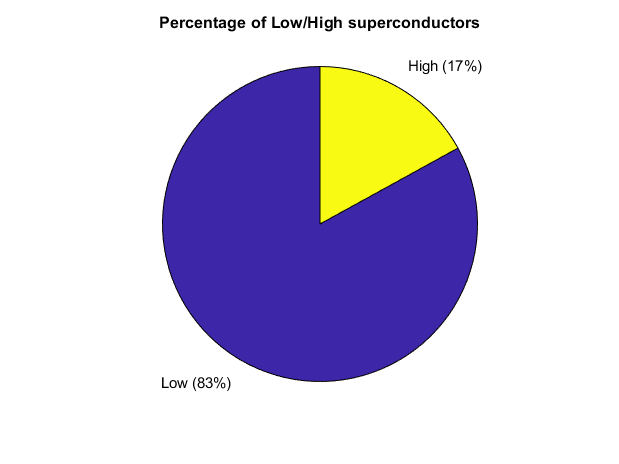

pie(scFeatures.TcClass)
title("Percentage of Low/High superconductors")

## Working with Missing Data (2-12)

Use [`ismissing`](matlab: doc ismissing) to determine the percentage of missing data within the dataset.

missingIdx = ismissing(scFeatures);
percMissing = nnz(missingIdx) / numel(missingIdx) * 100

percMissing = 0.8865

Visualize the location of missing data with [`imagesc`](matlab: doc imagesc)`.`

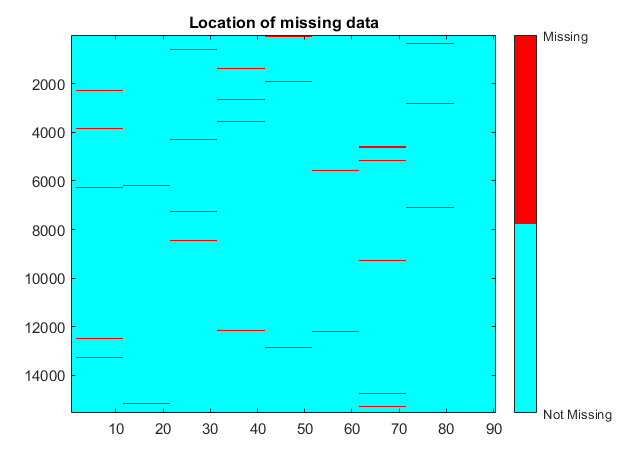

imagesc(missingIdx)
title("Location of missing data")
colorbar("Ticks", [0 1], ...
    "TickLabels", ["Not Missing", "Missing"])
cmap = flip(hsv(2));
colormap(cmap)

Remove all rows with missing values with [`rmmissing`](matlab: doc rmmissing)`.`

scFeaturesClean = rmmissing(scFeatures);

## Visualizing Data (2-13)

Create a [`histogram`](matlab: doc histogram) of the mean atomic mass.

histogram(scFeatures.MeanAtomicMass)

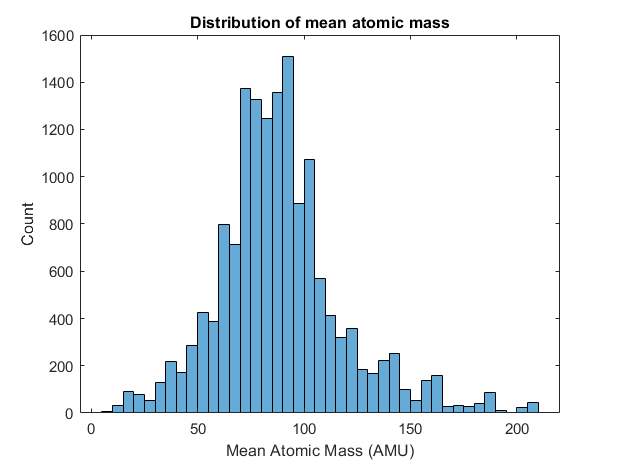

xlabel("Mean Atomic Mass (AMU)")
ylabel("Count")
title("Distribution of mean atomic mass")

Create box plots of mean atomic mass for low and high temperature superconductors using [`boxchart`](matlab: doc boxchart)`.`

boxchart(scFeatures.TcClass, scFeatures.MeanAtomicMass)

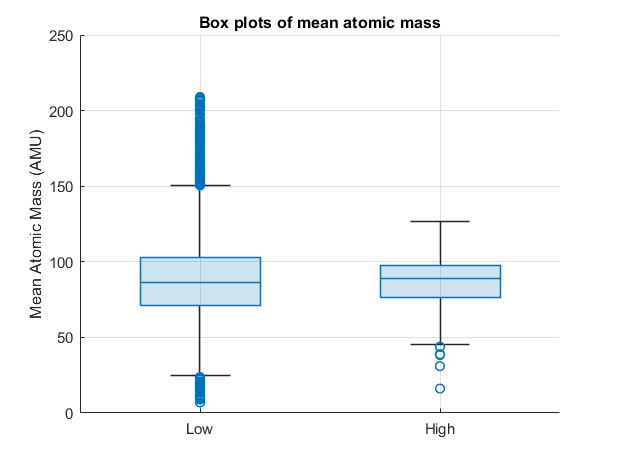

ylabel("Mean Atomic Mass (AMU)")
grid on
title("Box plots of mean atomic mass")

Use [`gscatter`](matlab: doc gscatter) to create a scatter plot of mean atomic mass and mean density, grouped by low/high $T_c$.

gscatter(scFeatures.MeanAtomicMass, scFeatures.MeanDensity, scFeatures.TcClass)

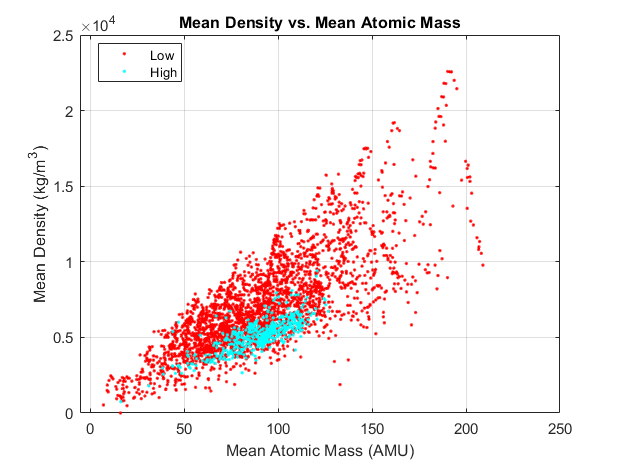

grid on
xlabel("Mean Atomic Mass (AMU)")
ylabel("Mean Density (kg/m^3)")
title("Mean Density vs. Mean Atomic Mass")

Create a drop down live control of `featureNames` to interactively plot histograms and box plots for any variable. 

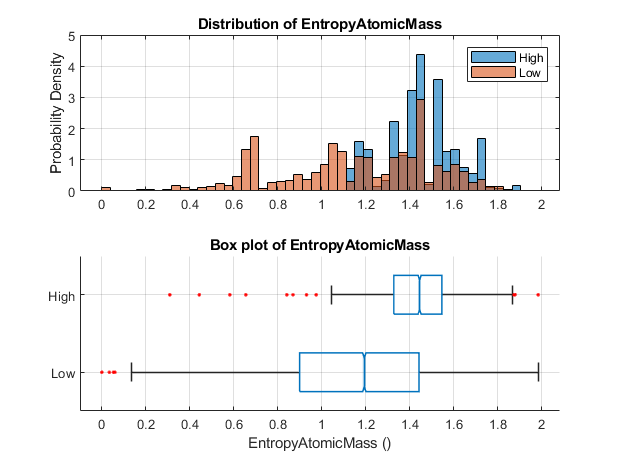

featureNames = string(scFeatures.Properties.VariableNames);
selVar = featureNames(6);
varData = scFeatures.(selVar);
varUnit = scFeatures.Properties.VariableUnits(selVar);
highTvar = varData(scFeatures.TcClass == "High");
lowTvar = varData(scFeatures.TcClass == "Low");
[dataMin, dataMax] = bounds(varData);
numBins = 50;
binEdges = linspace(dataMin, dataMax, numBins + 1);

figure
tiledlayout(2, 1)
ax1 = nexttile;
histogram(highTvar, binEdges, "Normalization", "pdf") % Hist. area = 1
hold on
histogram(lowTvar, binEdges, "Normalization", "pdf") % Hist. area = 1
ylabel("Probability Density")
title("Distribution of " + selVar)
grid on
legend("High", "Low")
ax2 = nexttile;
boxchart(scFeatures.TcClass, varData, ...
    "Orientation", "horizontal", ...
    "MarkerStyle", ".", ...
    "Notch", "on", ...
    "MarkerColor", "r")
grid on
title("Box plot of " + selVar)
xlabel(selVar + " " + varUnit)
linkaxes([ax1 ax2], "x")

Create drop down live controls to interactively visualize a scatter plot of any two variables. 

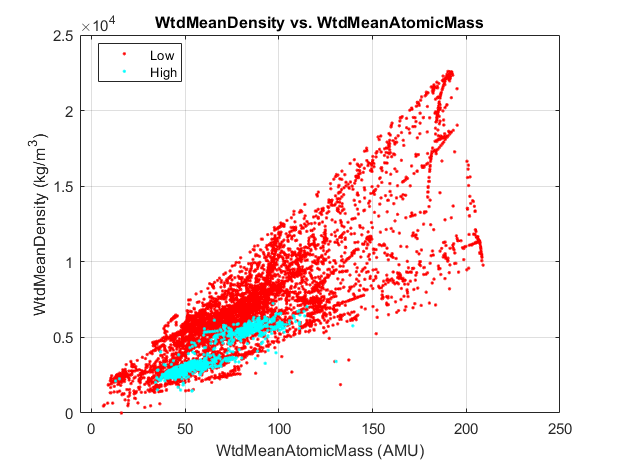

var1 = featureNames(3);
var2 = featureNames(33);
var1Units = scFeatures.Properties.VariableUnits(var1);
var2Units = scFeatures.Properties.VariableUnits(var2);
figure
gscatter(scFeatures.(var1), scFeatures.(var2), scFeatures.TcClass)
grid on
xlabel(var1 + " " + var1Units)
ylabel(var2 + " " + var2Units)
title(var2 + " vs. " + var1)

## Save preprocessed data (2-14)

save processedData scFeatures scFeaturesClean